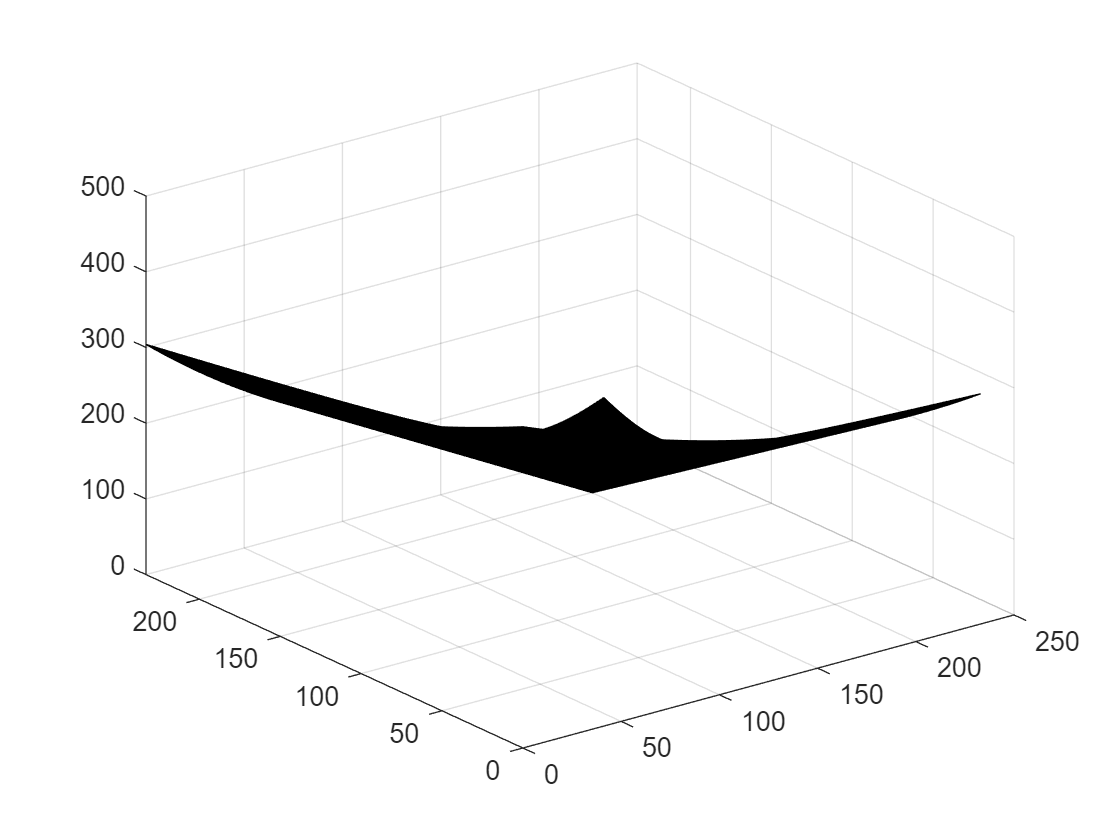

clear all
%% 定义函数输入
r=7;%最小转弯半径
Stepsize=0.01;%路径的生成间隔

sure=3;%保证安全的预留距离
% R=10+sure;


mapsize=200;
num=0;%%%%随机障碍物数量
R=[10,30];%%%障碍物半径范围;
num_obs_nocircle=0;
num_steps=100;%%%%边界上几个点
% Start_Point = [100,0,-pi/6];
% End_Point = [200,200,-pi/2];%[x,y,角度]

% Start_Point = [round(rand(1,2)*mapsize),-pi+rand(1)*2*pi];
% End_Point = [round(rand(1,2)*mapsize),-pi+rand(1)*2*pi];%[x,y,角度]

Start_Point = [0,0,-pi+rand(1)*2*pi];
End_Point = [200,200,-pi+rand(1)*2*pi];%[x,y,角度]

[outline_all,obs_no_circle,obs_no_circle_in]=obtain_obs_no_circle_all(num_obs_nocircle,mapsize,R,num_steps,Start_Point,End_Point,sure);


[obs,obs_no_circle,obs_no_circle_in,outline_all]=obtain_map(num,mapsize,Start_Point, End_Point,R,r,obs_no_circle,obs_no_circle_in,outline_all);%[x,y,障碍物的安全半径R]


r_search=15;%%探测半径
k_att=1.5;%计算引力需要的增益系数
k_rep=30;%计算斥力的增益系数，都是自己设定的。
total_field=obtian_field(mapsize+R(2)+sure,End_Point,outline_all,k_att,k_rep,r_search);


% load("0317_2.mat") 
Draw_map(Start_Point,End_Point,obs,sure,obs_no_circle,obs_no_circle_in);%绘制地图



[final_path,open,close]=A_dubins_nocircle(Start_Point,End_Point,obs,sure,r,obs_no_circle,obs_no_circle_in,outline_all,Stepsize,total_field);

Find Goal!!
历时 0.131082 秒。
运行时间: 0.13898


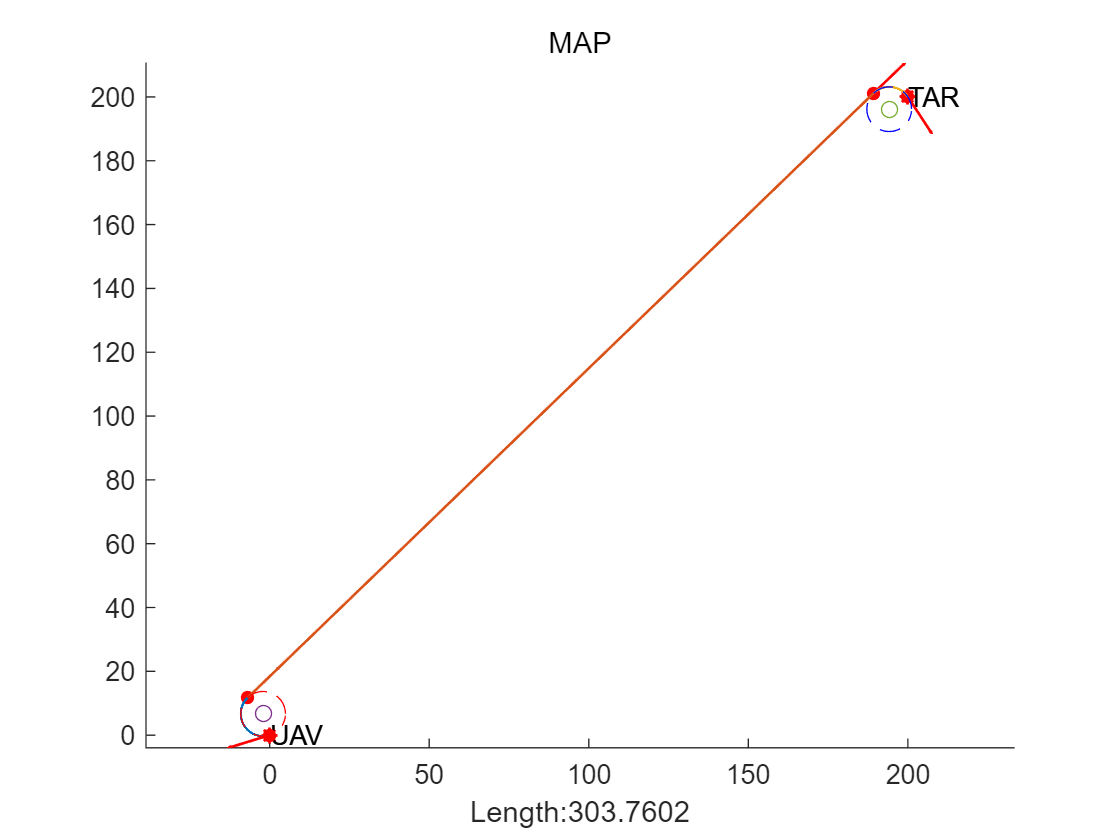

Draw_map(Start_Point,End_Point,obs,sure,obs_no_circle,obs_no_circle_in);%绘制地图
Draw_pathA_no_circle(final_path);
hold off


[draw_path,vtheta_all]=obtain_vtheta_drawpath_nocircle(final_path);


% 循环获取鼠标点击位置
disp('点击鼠标左键来添加障碍物，中键撤销上一个点，点击右键结束');

[outline_all_unknow,obs_no_circle_unknow,obs_no_circle_in_unknow]=obtain_unknow_obs_nocircle(Start_Point,End_Point,obs,sure,obs_no_circle,obs_no_circle_in,final_path,num_steps);


A_dubins_param{1}=Start_Point;
A_dubins_param{2}=End_Point;
A_dubins_param{3}=sure;
A_dubins_param{4}=r;
A_dubins_param{5}=draw_path;
%%%%%%%%%%%%%%APF参数
r_search=15;%%探测半径
k_att=1.5;%计算引力需要的增益系数
k_rep=30;%计算斥力的增益系数，都是自己设定的。
Stepsize_apf=1;%路径的生成间隔
fov=84;%%%°
K=1000;%%%%APF循环次数
apf_param=[fov,k_att,k_rep,K,r_search];


% angle_CCW_CW=[];






path_apf=[];
path_apf_all=[];
% obs_param_unknow=[obs_unknow_center,radius_unknow];
step_final=0;
step=Stepsize/Stepsize_apf;%%%%%%%%A_dubins和APF的路径点数目关系=>每10个A_dubins可能才是一个APF，用于搜索A_dubins路径是否安全时考虑
% ///////pointnum_apf*Stepsize_apf=pointnum_A_dubins*Stepsize=l(相同距离)pointnum_A_dubins=l/Stepsize
%  Stepsize_apf=pointnum_A_dubins*Stepsize/Stepsize_apf




step_param=[Stepsize_apf,Stepsize,step];
%%%%%%%%%%%%%%%障碍圆的点
num_obs=100;%%一个圆上几个点
obs_unknow=outline_all_unknow(:,1:2);
obs_know=outline_all(:,1:2);
obs_all=[obs_unknow;obs_know];


obs_param{1}=obs_all;
obs_param{2}=obs_unknow;
obs_param{3}=obs_no_circle;
obs_param{4}=obs_no_circle_in;
obs_param{5}=num_obs;
obs_param{6}=obs;
obs_param{7}=obs_no_circle_unknow;
obs_param{8}=obs_no_circle_in_unknow;

%%%%%%%%%%%%动态画图
figure




%%%%%%%%
point_id=[1;1];
i=1-Stepsize_apf/Stepsize;
% i=10000
% i=30000;
while i<length(draw_path)
% for i=1:Stepsize_apf/Stepsize:length(draw_path)
%     display(i)
    if ~isempty(path_apf)
        i=X_APF_final_id;
    else
        i=i+1/step;
    end


    hold off
    Draw_map(Start_Point,End_Point,obs,sure,obs_no_circle,obs_no_circle_in);%绘制地图
    Draw_obs_unknow_circle(obs_no_circle_unknow,obs_no_circle_in_unknow);%绘制地图 

    if i>=length(draw_path)
        i=length(draw_path);
    end

    point_append=[i;i-point_id(1,end)];
    point_id=[point_id,point_append];

    for map=3:length(point_id(1,:))
        if point_id(2,map)<=Stepsize_apf/Stepsize
                plot(draw_path(1,point_id(1,map-1):point_id(1,map)),draw_path(2,point_id(1,map-1):point_id(1,map)),'.','MarkerSize',5,'MarkerFaceColor','r','MarkerEdgeColor','r');
        end
    end


%     display([~isempty(path_apf),i])   
    path_apf=[];

%     hold off

    if ~isempty(path_apf_all)
        plot(path_apf_all(:,1),path_apf_all(:,2),'.','MarkerSize',5,'MarkerFaceColor','c','MarkerEdgeColor','c');
    end
%     hold on;
    quiver(draw_path(1,i),draw_path(2,i),15*cos(vtheta_all(i+1)),15*sin(vtheta_all(i+1)),'Color','r','LineWidth',1);
%     drawnow
    
    X_end_A_dubins(1)=draw_path(1,i); 
    X_end_A_dubins(2)=draw_path(2,i);
    angle=vtheta_all(i+1);

   

    %%%%针对新障碍物检测是否在感知视野内=>确定感知视野内的障碍物
    check_in=[];
    for j=1:length(obs_unknow)
        check_in=[check_in,pointInSector(obs_unknow(j,1),obs_unknow(j,2),X_end_A_dubins(1),X_end_A_dubins(2),r_search,angle,fov)];
    end


    obs_range_apf=find(check_in==1);%%%%探测感知视野内的障碍物的id=>obs_unknow(obs_range(j),1)为实际坐标

    draw_sector(angle,fov,X_end_A_dubins,r_search,obs_range_apf,obs_unknow)
    if ~isempty(obs_range_apf)
    %%%针对感知视野内的障碍物检查前面r_search部分内的已有路径是否安全
        path_safe=point_in_path(obs_unknow,obs_range_apf,draw_path,r_search/Stepsize,i);
    
        if ~path_safe
            display('APF start')
            text(-10,-10, 'APF start');pause(3)
%             X_APF_final(1)=draw_path(1,i+3*r_search/Stepsize);
%             X_APF_final(2)=draw_path(2,i+3*r_search/Stepsize);

            %%%APF算法
                X_now_APF(1)=X_end_A_dubins(1); %path是保存车走过的每个点的坐标。刚开始先将起点放进该向量。
                X_now_APF(2)=X_end_A_dubins(2);

                r_max=ceil(estimate_obs_unknow_r(obs_range_apf,obs_unknow,X_now_APF));
%                 r_max=0;
                [X_APF_final,X_APF_final_id]=obtain_apf_final(i+(r_search+3*r_max)/Stepsize,2/step,draw_path,obs_unknow,obs_range_apf,obs_no_circle);
                plot(X_APF_final(1),X_APF_final(2),'x')
%                 obs_range=obs_range_apf;
                [path_apf,path_apf_all,X_APF_final_id]=APF(vtheta_all,X_end_A_dubins,angle,X_now_APF,X_APF_final,step_param,obs_param,apf_param,A_dubins_param,path_apf_all,path_apf,X_APF_final_id,i);
                    
        end
    end


    pause(0.0001);
end